# Sasp Project: Dereverb

## Part 1: Reverberation

### RIR generation

Exploit this tool: [https://www.audiolabs-erlangen.de/fau/professor/habets/software/rir-generator](https://www.audiolabs-erlangen.de/fau/professor/habets/software/rir-generator) to generate a simple RIR.

Compile the tools:

mex -setup

MEX configured to use 'Microsoft Visual C++ 2019 (C)' for C language compilation.

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN


mex RIR-Generator-master/rir_generator.cpp

Building with 'Microsoft Visual C++ 2019'.
MEX completed successfully.


Select parameters for the room (adopted same sintax of site):

c = 340;                     % Sound velocity (m/s)
fs = 16000;                  % Sample frequency (samples/s)
r = [2, 1.5, 2];             % Receiver position [ x y z ] (m)
s = [2, 8.5, 2];             % Source position [ x y z ] (m)
L = [10, 20, 10];            % Room dimensions [ x y z ] (m)
beta = 0.5;                  % Reverberationtime (s)
% other optional parameters
% nsample = 4096;              % Number of samples
% mtype = 'hypercardioid';     % Type of microphone
% order = -1;                  % −1 equals maximum reflection order!
% dim = 3;                     % Room dimension
% orientation = [pi/2 0];      % Microphone orientation [azimuth elevation] in radians
% hp_filter = 1;               % Enable high-pass filter

Generated RIR (high computation, run only one time):

h = rir_generator(c, fs, r, s, L, beta, nsample);

Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.


h = h';

Plot RIR:

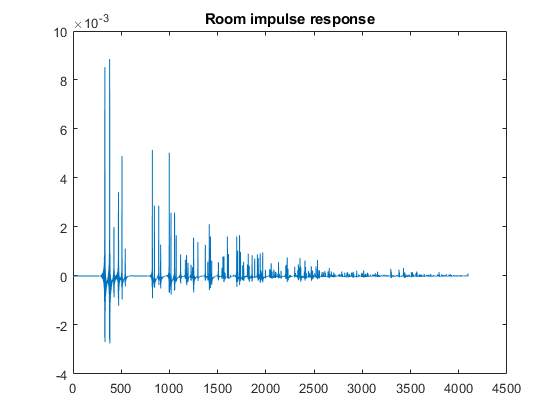

plot(h)
title("Room impulse response")

Si boh ma fa schifo sta cosa

Import a second RIR

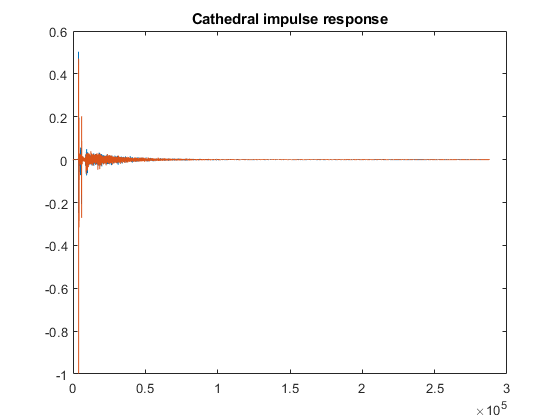

[h1,fs1] = audioread('1st-baptist-nashville/stereo/1st_baptist_nashville_balcony.wav');
plot(h1)
title("Cathedral impulse response")

Adjust the sampling frequency in order to have same $f_s$ of the RIR:

h1 = resample(h1,48000,fs1);

### Signal generation

Import a simple signal (handclap) to be reverberated and adapt the sampling frequency to match the RIR.

[clap,fs_clap] = audioread('Clap808.wav'); 

Sinusoidal signal

Plot signals:

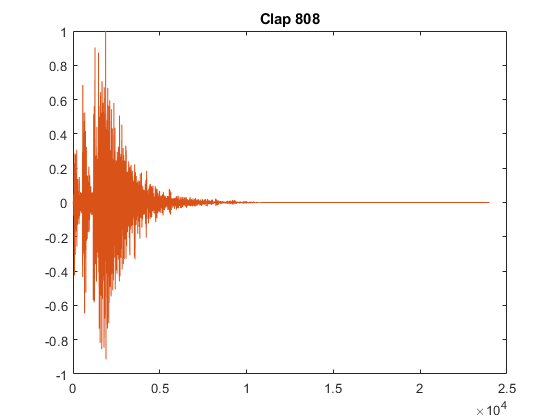

plot(clap)
title("Clap 808")

### Reverberation of signals

We have 3 alternatives: time convolution, fftfilt (OLA matlab), OLA

#### Signal Convolution

Apply simple convolution in time domain

% rev_clap = conv(h1(:,1), clap(:,1));

#### Function fftfilt

Apply OLA algorithm to compute convolution (multiplication in frequency domain)

rev_clap = fftfilt(clap(:,1), h1(:,1));

#### OLA algorithm

Apply OLA algorithm as seen at lesson

### Results

Reverberated sound + audio samples

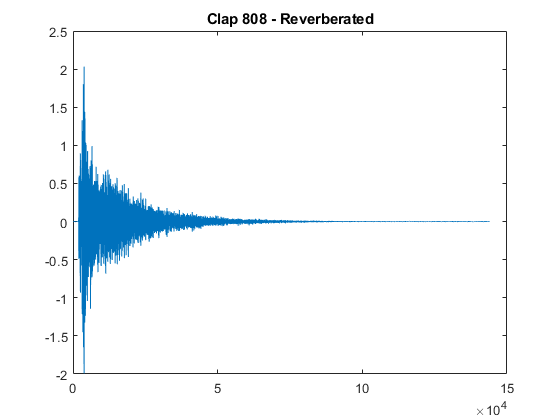

plot(rev_clap)
title("Clap 808 - Reverberated")

Dry signal:

soundsc(clap, 48000);

Reverberated signal:

soundsc(rev_clap, 48000);

## Part 2: Dereverberation